# TUTORIEL: Comment construire une matrice de conception avec des variables indicatrices pour optimiser un modèle de régression multinomial sur MATLAB

## Qu'est-ce qu'une régression logistique multinomiale ?

En analyse statistique, les modèles de **régression** sont un moyen d'estimer la relation entre une variable d'intérêt, appelée **variable dépendante** (ou réponse), et une ou plusieurs **variables indépendantes** (ou prédicteurs). Cela nécessite des observations $\left(x_i ,y_i \right)$, $i=1,\ldots,n$, d'une réponse $y_i$  associée à des valeurs de prédicteurs $x_i$, auxquelles un modèle est ensuite ajusté afin de prédire$Y$ pour différentes valeurs de $X$ (comme il s'agit de variables aléatoires, j'utilise ici des majuscules pour les distinguer des observations, qui sont des échantillons de ces variables aléatoires). L'exemple le plus célèbre est probablement une **régression linéaire simple** entre des variables dépendante et indépendante qui sont des quantités continues, par exemple lorsqu'on cherche à prédire le poids à partir de la taille. Le modèle repose sur l'hypothèse que, étant donné le prédicteur, la réponse est égale à une fonction linéaire de celui-ci plus une erreur aléatoire :


$$y_i =\beta_0 +\beta_1 x_i +\varepsilon_i$$


où $\varepsilon_i$ est un terme d'erreur aléatoire d'espérance nulle. Avec cette hypothèse, **le modèle de régression linéaire décrit l'espérance de Y conditionnellement à chaque observation **$x_{i\;} \;$ sous la forme d'une simple droite de tendance, d'ordonnée à l'origine $\beta_0$ et de pente $\beta_1$ :


$$\mathrm{E}\left(Y|x_i \right)=\beta_0 +\beta_1 x_i$$


La question centrale, qui est la même pour tous les modèles de régression, est de trouver les valeurs des paramètres qui reflètent le mieux les données selon un certain critère : pour la régression linéaire, on minimise la somme des carrés des écarts entre les observations $y_i$ et les valeurs attendues  $E\left(Y|x_i \right)$. Une première extension consiste à admettre plusieurs prédicteurs$x_1 ,\ldots,x_p$,, rassemblés dans le vecteur $\mathbf{x}={\left(x_1 ,\ldots,x_p \right)}^T$, auquel cas le modèle devient :


$$\mathrm{E}\left\lbrack Y|\mathbf{x}\right\rbrack =\beta_0 +\beta_1 x_1 +\beta_2 x_2 +\ldotp \ldotp \ldotp +\beta_p x_p =\beta_0 +\sum_{j=1}^p \beta_j x_j$$


Parfois, la variable que l'on veut prédire n'est pas une quantité continue comme la taille mais une catégorie, c'est-à-dire une **variable nominale**. Dans le cas le plus simple, il n'y a que deux catégories, par exemple `fumeur` vs `non-fumeur` ou `oui` vs `non`. On ne peut pas appliquer directement un modèle linéaire à de tels résultats, car ce ne sont pas des nombres, et si on les codait par 0 et 1, une fonction linéaire de $\mathbf{x}$ ne garantirait pas que la probabilité prédite reste comprise entre 0 et 1. L'astuce au cœur de **la régression logistique** consiste à modéliser la probabilité$\pi \left(\mathbf{x}\right)=P\left(Y=\textrm{yes}\left|\mathbf{x}\right.\right)$ à travers son ***log-odds*** (ou logit), le logarithme de la **cote** (*odds* en anglais, le rapport de deux probabilités) $\pi /\left(1-\pi \right)$, qui peut prendre n'importe quelle valeur réelle, et à faire de cette quantité une fonction linéaire des prédicteurs :


$$\log \frac{\pi \left(\mathbf{x}\right)}{1-\pi \left(\mathbf{x}\right)}=\beta_0 +\sum_{j=1}^p \beta_j x_j$$


Sur le plan technique, sans entrer dans les détails, le critère utilisé pour optimiser les coefficients $\beta$ n'est plus la somme des carrés des écarts, que l'on minimise en régression linéaire, mais la vraisemblance des observations, que l'on maximise. Remqarquez comment, du fait qu'il n'y a que deux issues possibles, augmenter la valeur d'un des coefficients augmente la cote de l'issue de référence, et donc la probabilité de cette issue.

Enfin, lorsqu'il y a plus de deux catégories, on utilise une **régression logistique multinomiale**. Soient une variable dépendante $Y$ prenant ses valeurs dans$\lbrace 1,\ldots,K\rbrace$ , et la probabilité conditionnelle $\pi_k \left(\mathbf{x}\right)=P\left.\left(Y=k\right|\mathbf{x}\right)$, de sorte que$\pi_1 +\cdots +\pi_K =1$. Une catégorie, ici $K$, est choisie comme référence, et on modélise les log-odds de chacune des autres catégories relativement à celle-ci, ce qui donne un système de $K-1$ équations. Dans le cas que je vais traiter ici, on s'intéresse aux probabilités de choisir des leviers dans une tâche de bandit à 3 bras. L'issue d'un essai donné est nominale, par exemple `levier 1 choisi`, et comme il y a $K=3$  choix possibles, on cherche les paramètres d'un système de 2 équations qui, en prenant le levier 3 comme référence, s'écrit :


$$\left\lbrace \begin{array}{c}
\log \frac{\pi_1 \left(\mathbf{x}\right)}{\pi_3 \left(\mathbf{x}\right)}=\beta_{1,0} +\sum_{j=1}^p \beta_{1,j} x_j =\eta_1 \\
\log \frac{\pi_2 \left(\mathbf{x}\right)}{\pi_3 \left(\mathbf{x}\right)}=\beta_{2,0} +\sum_{j=1}^p \beta_{2,j} x_j =\eta_2 
\end{array}\right.$$


Ici, $\beta_{k,j}$ est le coefficient du prédicteur $j$ dans l'équation de la catégorie $k$ ($j=0$ correspondant à l'ordonnée à l'origine), et $\eta_k$ est la somme pondérée des prédicteurs de l'équation $k$. Notez que les prédicteurs$x_j$ sont les mêmes dans les deux équations : **les prédicteurs sont partagés entre toutes les équations, et c'est la façon dont ils sont transformés par les coefficients de chaque équation qui donne des log-odds différents pour chaque réponse**. Une fois les paramètres optimisés, on peut retrouver les probabilités estimées à partir de deux faits. Premièrement, la définition du log-odds donne $\pi_k =\pi_3 e^{\eta_k }$ pour $k=1,2$. Deuxièmement, les probabilités somment à un, de sorte que:


$$\pi_3 \left(1+e^{\eta_1 } +e^{\eta_2 } \right)=\pi_1 +\pi_2 +\pi_3 =1$$


En résolvant pour $\pi_3$ et en substituant, la probabilité estimée de chaque action est:


$$\left\lbrace \begin{array}{c}
\pi_1 =\frac{e^{\eta_1 } }{1+e^{\eta_1 } +e^{\eta_2 } }\\
\pi_2 =\frac{e^{\eta_2 } }{1+e^{\eta_1 } +e^{\eta_2 } }\\
\pi_3 =\frac{1}{1+e^{\eta_1 } +e^{\eta_2 } }
\end{array}\right.$$


Il est intéressant de remarquer la complexité de ces probabilités, puisqu'elles dépendent toutes des deux prédicteurs linéaires $\eta \;$ : $\eta_1$ peut augmenter ce qui accroît effectivement le log-odds de choisir le levier 1 par rapport au levier 3 sans nécessairement augmenter $\pi_1$ lui-même si $\eta_2$ est également en train de varier.

## Le codage indicateur

J'ai expliqué comment traiter les variables dépendantes nominales ; vient maintenant le tour des variables indépendantes nominales. Ici, on ne peut pas utiliser l'astuce précédente consistant à remplacer les variables par des log-odds, car les observations $\mathbf{x}$, qui sont certes des échantillons de la variable aléatoire $X$, sont néanmoins fixées une fois observées. Le **codage indicateur** (*dummy coding*) résout ce problème en remplaçant les prédicteurs nominaux par$K-1$ **variables indicatrices**, où $K$ est le nombre total de catégories. Chaque variable indicatrice vaut 1 si l'observation appartient à une catégorie donnée et 0 sinon. La catégorie omise est la référence (ou catégorie par défaut), identifiée par le fait que toutes les variables indicatrices valent 0. D'autres schémas de codage existent, par exemple le codage par effets avec les valeurs 1, 0 et -1, mais ils modifient l'interprétation des coefficients et je ne les utiliserai pas. À titre d'exemple, si l'on veut prédire la taille en fonction du sexe, on introduit une variable indicatrice $d$  égale à 1 si le sujet est une femme et à 0 s'il s'agit d'un homme et effectuer une régression linéaire simple comme auparavant avec cette nouvelle variable:


$$y_i =\beta_0 +\beta_1 d_i +\varepsilon_{i\;}$$


La signification de$\beta_0$ et de$\beta_1$ découle directement de l'espérance conditionnelle de $Y$. Pour un homme, ${E\left(Y|d=0\right)=\;\beta }_0$ est la taille attendue d'un homme (estimée par la taille moyenne des hommes de l'échantillon) ; pour une femme, ${E\left(Y|d=1\right)=\;\beta }_0 +\beta_1$, ce qui signifie que $\beta_1$ est la différence de taille attendue entre les femmes et les hommes. Avec trois catégories, on utiliserait deux variables indicatrices, et chaque coefficient serait la différence de résultat attendu entre cette catégorie et la catégorie de référence.

## Simulation de quelques données

Nous sommes maintenant prêts à aborder l'objectif principal de ce tutoriel, qui est d'ajuster une régression logistique multinomiale à des données collectées dans une **tâche de bandit à plusieurs bras**. Ces tâches, qui sont un problème classique **d'apprentissage par renforcement** couramment utilisé en neurosciences, sont constituées d'essais discrets au cours desquels les sujets doivent choisir une action parmi plusieurs dans l'espoir d'obtenir une récompense. Les récompenses et les choix passés peuvent servir de prédicteurs dans un modèle de régression logistique afin de déterminer l'impact de ces événements passés sur les choix actuels, comme dans l'étude de [**Lau and Glimcher (2005)**](https://doi.org/10.1901/jeab.2005.110-04), qui a utilisé la régression logistique pour étudier les choix de singes dans une tâche à deux alternatives et a montré que l'impact des récompenses passées décroissait avec le temps. Cette étude m'a incité à tester une régression logistique multinomiale plus complexe lors de l'analyse d'une tâche de bandit à trois bras ([**Cinotti et al. (2024)**](https://doi.org/10.1111/ejn.16449)), ce qui s'est révélé plus difficile que prévu, si bien que j'ai finalement eu recours dans ce papier à de simples régressions logistiques optimisées séparément pour chaque action. J'ai depuis eu l'occasion de revenir sur cette technique et de finalement la maîtriser, ce qui m'a poussé à écrire ce tutoriel dans l'espoir qu'il puisse aider d'autres personnes confrontées à des difficultés similaires.

Pour commencer, il nous faut des données : ce sera un simple jeu de données synthétiques de 900 essais, avec les choix et les récompenses enregistrés. Cette expérience virtuelle sera composée de blocs de 100 essais au cours desquels l'un des leviers sera récompensé avec une probabilité de 60 % s'il est sélectionné, tandis que les deux autres le seront avec une probabilité de 20 % chacun. Pour générer des choix plausibles, nous utiliserons un modèle de Q-learning avec un taux d'apprentissage de 0,1, qui sert aussi de taux d'oubli pour les valeurs des leviers non sélectionnés, associé à une sélection d'action softmax avec une température inverse de 5. Si vous ne comprenez pas ce que cela signifie, tout ce que vous avez besoin de retenir, c'est que c'est une manière de générer des données intéressantes.

%% Simulate some behavioural data

rng(1);  % make the example reproducible

trials_per_block = 100;
schedule = repmat([1, 2, 3], 1, 3); % identities of the best lever in each block of trials
n_blocks = length(schedule);
n_trials = n_blocks * trials_per_block;

data = struct('choices', nan(n_trials, 1), 'rewards', nan(n_trials,1)); % one entry per trial

% initialise the Q-learner
Q = zeros(1, 3);
learningRate = 0.1;
inverseTemperature = 5;

for trial = 1 : n_trials
    
    % given trial number, get the current best lever
    block = ceil(trial / trials_per_block);
    best = schedule(block);
    
    % generate a random choice based on current Q-values
    probs = exp(inverseTemperature * Q) ./ sum(exp(inverseTemperature * Q));
    choice = randsample(1:3, 1, true, probs);
    
    % generate a stochastic reward based on the choice
    reward = rand < (choice == best) * 0.6 + (choice ~= best) * 0.2;

    % update Q-values for next step
    Q = (1 - learningRate) * Q; % forgetting step that applies to all levers
    Q(choice) = Q(choice) + learningRate * reward; % learning that applies only to the selected lever    
   
    % store trial observations
    data.choices(trial) = choice;
    data.rewards(trial) = reward;
end

Pour vous faire une idée de ce à quoi ressemblent ces données, voici un graphique rapide des taux de sélection de chaque levier, calculés par moyennes mobiles sur 20 essais. Vous devriez observer des périodes distinctes pendant lesquelles les trois leviers dominent tour à tour pendant des blocs d'environ 100 essais, ce qui illustre la façon dont l'algorithme de Q-learning suit correctement le programme de récompenses. Les choix restent néanmoins bruités, et si vous avez conservé la même graine aléatoire, vous remarquerez que dans le quatrième bloc (essais 300-400), le taux de sélection du levier 1, qui était pourtant le meilleur levier de ce bloc, était assez faible.

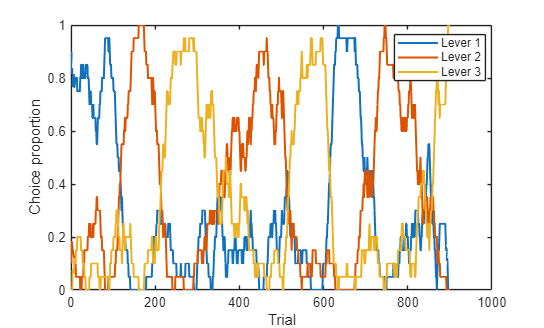

%% running averages of lever selection for quick visualisation

figure()
windowSize = 20;
runningChoiceRate = movmean(data.choices == (1:3), windowSize, 1);

plot(runningChoiceRate, 'LineWidth', 1.5);
xlabel('Trial');
ylabel('Choice proportion');
legend('Lever 1', 'Lever 2', 'Lever 3', 'Location', 'best');

## Construction de la matrice de conception

Nous nous demandons maintenant si les choix et les récompenses précédents permettent de prédire le choix de l'essai courant. Soient $c_t \in \lbrace 1,2,3\rbrace$ le levier choisi et $r_t \in \lbrace 0,1\rbrace$ la récompense obtenue à l'essai $t$. À ce stade, la conception de la régression, c'est-à-dire le choix des prédicteurs et la façon de les encoder, dépend vraiment de vous. Dans mon cas, je voulais utiliser les $$$L=10$$$ derniers essais (**l'horizon**) pour prédire $c_t$, avec cinq prédicteurs pour chaque essai de l'horizon passé $\ell =1,\ldots,L$ : des variables indicatrices pour `avoir choisi le levier 1`, `avoir choisi le levier 2`, `avoir été récompensé sur le levier 1`, `avoir été récompensé sur le levier 2` et `avoir été récompensé sur le levier 3`, ce qui fait$p=5L=50$ prédicteurs au total, et le modèle à ajuster est le système d'équations introduit plus haut, avec  ${\mathbf{x}}_t ={\left(x_{t,1} ,\ldots,x_{t,p} \right)}^T$ comme prédicteurs:


$$\log \frac{P\left.\left(c_t =k\right|{\mathbf{x}}_t \right)}{P\left.\left(c_t =3\right|{\mathbf{x}}_t \right)}=\beta_{k,0} +\sum_{j=1}^p \beta_{k,j} x_{t,j} ,~~k=1,2$$


Quelques remarques sur cet encodage. Premièrement, il n'y a pas de prédicteur pour le fait d'avoir choisi le levier 3, ce qui signifie que le levier 3 est le levier de référence, comme ci-dessus. Deuxièmement, les trois derniers prédicteurs sont des combinaisons choix-récompense : `récompensé sur le levier k` signifie que le levier $k$ a été choisi et récompensé ; le prédicteur 3 par exemple représente l'effet d'avoir été récompensé sur le levier 1 en plus de l'effet d'avoir sélectionné le levier 1, qui est déjà encodé par le prédicteur 1. D'autres encodages pourraient séparer ces effets différemment, et ce choix a son importance lorsqu'on cherche à interpréter les résultats finaux. La **matrice de conception**$X$, aussi apellée **matrice de régression**, est la collection des prédicteurs pour tous les essais ; elle a une ligne par observation (essai) et une colonne par prédicteur. Les choix $c_t$ à chaque essai sont de même rassemblés dans **le vecteur de réponse **$y$.

horizon = 10;
n_levers = 3;
ref_lever = 3; % reference lever (the dummy coding below assumes lever 3)
non_ref_levers = setdiff(1:n_levers, ref_lever);

n_choice_cols = numel(non_ref_levers);
n_reward_cols = n_levers;

cols_per_lag = n_choice_cols + n_reward_cols;
n_pred = cols_per_lag * horizon;

Nous pouvons maintenant construire$X$ et $y$.

% We lose the first 'horizon' trials because there is not enough previous history to construct the predictors.
n_rows = n_trials - horizon;

X = zeros(n_rows, n_pred);
y = zeros(n_rows, 1);

row = 1;

for t = horizon + 1 : n_trials % we go through trials filling in the rows of X and y
    
    % Current choice is the response variable
    y(row) = data.choices(t);
    
    % -------------------------------------------------------------
    % Construct predictors from previous trials
    % -------------------------------------------------------------
    
    for lag = 1 : horizon % we repeat these same steps for each lag trial in turn
        
        % First column belonging to this lag
        lag_offset = (lag-1) * cols_per_lag;
        
        past_choice = data.choices(t-lag);
        past_reward = data.rewards(t-lag);
        
        % ---------------------------------------------------------
        % Previous choice
        % ---------------------------------------------------------
        
        % Lever 3 is the reference category, so it does not get
        % its own dummy variable.
        if past_choice == 1
            X(row, lag_offset + 1) = 1;
        elseif past_choice == 2
            X(row, lag_offset + 2) = 1;
        end
        
        % ---------------------------------------------------------
        % Previous rewarded choice
        % ---------------------------------------------------------
        
        % If the previous choice was rewarded, activate the
        % indicator corresponding to the chosen lever.
        if past_reward == 1            
            reward_col = lag_offset + ...
                n_choice_cols + past_choice;            
            X(row, reward_col) = 1;            
        end        
    end    
    row = row + 1;
end

Pour mieux comprendre à quoi ressemble$X$, il est utile de regarder côte à côte les premières lignes des données originales et de $X$ :

%  Original data: trial number, choice and reward in one table
n_show = 15;
dataTable = table((1:n_show)', data.choices(1:n_show), data.rewards(1:n_show), ...
    'VariableNames', {'Trial', 'Choice', 'Reward'});
disp(dataTable)

    Trial    Choice    Reward
    _____    ______    ______

      1        2         0   
      2        1         1   
      3        1         1   
      4        1         1   
      5        1         1   
      6        1         0   
      7        1         0   
      8        1         0   
      9        1         1   
     10        1         1   
     11        2         0   
     12        1         0   
     13        3         0   
     14        1         1   
     15        1         0   




% First rows of X, labelled by the trial they predict
n_rows_shown = 5;
lags_shown   = 2;   % lags 1 and 2 

% Readable column names, e.g. Chose1_L1, Chose2_L1, Rew1_L1, ..., Rew3_L2
baseNames = [compose("Chose%d", non_ref_levers), compose("Rew%d", 1:n_levers)];
predNames = strings(1, 0);
for lag = 1 : lags_shown
    predNames = [predNames, baseNames + "_L" + lag];
end

XTable = array2table(X(1:n_rows_shown, 1:numel(predNames)), ...
    'VariableNames', cellstr(predNames));

% Add the trial each row predicts
XTable = addvars(XTable, (horizon + 1 : horizon + n_rows_shown)', ...
    'Before', 1, 'NewVariableNames', 'Trial');
disp(XTable)

    Trial    Chose1_L1    Chose2_L1    Rew1_L1    Rew2_L1    Rew3_L1    Chose1_L2    Chose2_L2    Rew1_L2    Rew2_L2    Rew3_L2
    _____    _________    _________    _______    _______    _______    _________    _________    _______    _______    _______

     11          1            0           1          0          0           1            0           1          0          0   
     12          0            1           0          0          0           1            0           1          0          0   
     13          1            0           0          0          0           0            1           0          0

La première ligne de$X$ correspond à l'essai 11, et les cinq premières colonnes décrivent ce qui s'est passé à l'essai 10 où, à condition que la graine aléatoire n'ait pas été modifiée, le levier 1 a été sélectionné et récompensé, de sorte que $X\left(1,1\right)=1$ et $X\left(1,3\right)=1$. La deuxième ligne de $X$ correspond à l'essai 12, de sorte que les événements de l'essai 10 sont décalés vers les colonnes 6 à 10, tandis que les colonnes 1 à 5 décrivent l'essai 11, où l'agent a choisi le levier 2 sans être récompensé.

## Optimisation du modèle de régression

Nous avons maintenant construit la matrice $X$, qui contient l'historique comportemental de l'agent, et le vecteur $y$, qui contient le choix effectué à l'essai courant. Pour horizon = 10, il y a 5 prédicteurs par décalage × 10 décalages = 50 prédicteurs, donc $X$ a 50 colonnes. Les cinq premières colonnes décrivent l'essai immédiatement précédent (décalage 1), les cinq suivantes décrivent l'essai d'avant (décalage 2), et ainsi de suite. Pour ajuster le modèle de régression multinomiale par maximum de vraisemblance, nous utilisons la fonction intégrée `mnrfit`. Les versions récentes de MATLAB proposent aussi une fonction plus sophistiquée, `fitmnr`, mais j'ai choisi `mnrfit` parce que la construction de la matrice de design $X$ à codage indicateur rend l'encodage des prédicteurs plus transparent.

% Fit the multinomial logistic regression
[B, ~, ~] = mnrfit(X, y, 'Model', 'nominal');

La sortie $B$ contient les coefficients ajustés ${\overset{̂}{\beta} }_{k,j}$ du modèle. Elle a deux colonnes, la première pour le log-odds de choisir le levier 1 plutôt que le levier 3 ($k=1$), et la seconde pour le log-odds du levier 2 par rapport au levier 3 ($k=2$). Elle comporte 51 lignes : la première correspond aux ordonnées à l'origine ${\overset{̂}{\beta} }_{1,0}$ et ${\overset{̂}{\beta} }_{1,0}$, et les 50 suivantes aux coefficients des prédicteurs, de sorte que $\textrm{B}\left(j+1,k\right)={\overset{̂}{\beta} }_{k,j}$. Pour vérifier que le modèle fonctionne, vous pouvez calculer et tracer les probabilités prédites de chaque action à l'aide de la fonction `mnrval`, des coefficients ajustés $B$ et des données originales $X$ (au lieu de réutiliser $X$ comme je le fais ici, la méthode recommandée consisterait plutôt à mettre de côté une partie des données pour servir de test).

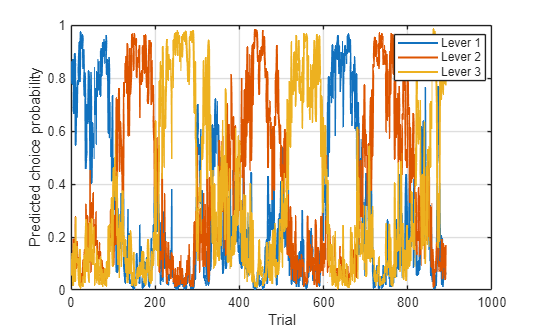

% Evaluate fitted choice probabilities on the observed predictors

P = mnrval(B, X);

figure()
plot(P, 'LineWidth', 1.5);
xlabel('Trial');
ylabel('Predicted choice probability');
legend('Lever 1', 'Lever 2', 'Lever 3', 'Location', 'best');
grid on;

Par rapport aux moyennes mobiles que nous avons tracées plus haut, les probabilités ajustées reproduisent les grandes tendances des données originales. On voit la sélection des différents leviers alterner en intensité d'un bloc à l'autre et, à moins que vous n'ayez changé la graine aléatoire, vous devriez constater que le quatrième bloc, dans lequel l'agent avait du mal à choisir le bon levier 1, est également ambigu du point de vue du modèle optimisé, ce qui reproduit donc une particularité des données originales.

## Une tentative malavisée d'interpréter les coefficients du modèle

À l'instar de [**Lau and Glimcher (2005)**](https://doi.org/10.1901/jeab.2005.110-04), vous pourriez vous contenter de tracer certains des coefficients ajustés pour voir comment les prédicteurs passés affectent les choix (figure 6 de cette publication). Une stratégie évidente pourrait consister à examiner séparément les impacts d'avoir été récompensé sur un levier et d'avoir sélectionné un levier sans nécessairement avoir été récompensé, sur le log-odds de ce même levier, comme mesures respectives de **l'effet du renforcement** et de **la persévération du choix** sur le comportement. Dans le cas du levier 1, les coefficients du prédicteur levier 1 choisi se trouvent aux lignes 2, 7, 12, etc. de $B$ et les coefficients du prédicteur levier 1 récompensé aux lignes 4, 9, 14, etc. Pour le levier 2, nous nous intéressons aux coefficients de levier 2 choisi (lignes 3, 8, 13, ...) et de levier 2 récompensé (lignes 5, 10, 15, ...).

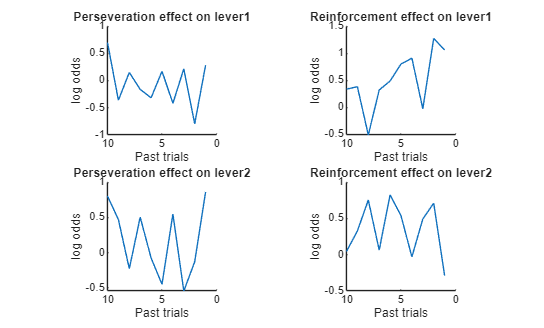

figure()

subplot(2,2,1)
hold on
plot(1 : horizon, B(2 : cols_per_lag : end,1))
title('Perseveration effect on lever1')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

subplot(2,2,2)
hold on
plot(1 : horizon, B(4 : cols_per_lag : end,1))
title('Reinforcement effect on lever1')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

subplot(2,2,3)
hold on
plot(1 : horizon, B(3 : cols_per_lag : end,2))
title('Perseveration effect on lever2')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

subplot(2,2,4)
hold on
plot(1 : horizon, B(5 : cols_per_lag : end,2))
title('Reinforcement effect on lever2')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

Alors que les autres coefficients ne montrent pas de tendance évidente, les coefficients associés aux choix récompensés sur le levier 1 sont positifs et tendent à diminuer à mesure que l'on remonte dans le passé, ce qui suggère un impact positif et décroissant des récompenses passées sur la sélection du levier 1. Cependant, contrairement à l'étude originale de [**Lau and Glimcher (2005)**](https://doi.org/10.1901/jeab.2005.110-04), qui reposait sur une simple régression logistique à deux issues possibles, l'interprétation de cette observation est plus délicate qu'il n'y paraît. En effet, comme je l'ai déjà souligné, chaque coefficient$\beta_{k,j}$ nous indique comment le prédicteur$j$ affecte le log-odds du levier $k$  par rapport au levier 3, plutôt que la façon dont se comporte la probabilité de choix $\pi_k$, qui est la quantité qui nous intéresse réellement. En outre, il ne faut pas oublier que les prédicteurs sont partagés entre les deux log-odds, en sorte qu'obtenir une récompense sur le levier 1 peut également augmenter la probabilité de re-sélectionner ce levier en diminuant le log-odds du levier 2 plutôt qu'en jouant sur le log-odds du levier 1. Cette inter-dépendance des log-odds pourrait expliquer pourquoi les autres coefficients semblent bruités à première vue. Pour savoir comment les prédicteurs affectent les probabilités de choix, il faut donc tenir compte des autres alternatives, un sujet pour une autre fois.

## **Références**

- Lau, B. and Glimcher, P.W. (2005), Dynamic Response-By-Response Models of Matching Behavior in Rhesus Monkeys. Journal of the Experimental Analysis of Behavior, 84: 555-579. https://doi.org/10.1901/jeab.2005.110-04

- Cinotti, F., Coutureau, E., Khamassi, M., Marchand, A. R., & Girard, B. (2024). Regulation of reinforcement learning parameters captures long-term changes in rat behaviour. European Journal of Neuroscience, 60(4), 4469–4490. https://doi.org/10.1111/ejn.16449